syms s;
[n1, d1] = deal((- 6)*s^3 + 3*s^2 + 4*s, s^5 - 3*s^4 + 7*s^3 - 3*s^2 - 4*s + 10);
[n2, d2] = deal((-26)*s^2, s^5 + 5*s^4 + 15*s^3 + 25*s^2 + 24*s + 10);
[n3, d3] = deal(7*s^4 + 12*s^3 +18*s^2+52*s-1, s^5 - 2*s^4 + 3*s^3 + 8*s^2 - 18*s + 20);
[num, dem] = deal(n1, d1);




n_coeffs = sym2poly(num);
d_coeffs =  sym2poly(dem);
sys_i = tf(n_coeffs, d_coeffs)

sys_i =
 
           -6 s^3 + 3 s^2 + 4 s
  --------------------------------------
  s^5 - 3 s^4 + 7 s^3 - 3 s^2 - 4 s + 10
 
Continuous-time transfer function.
Model Properties



figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ разомкнутой системы 3'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

%ops.FreqScale = 'Linear';
   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



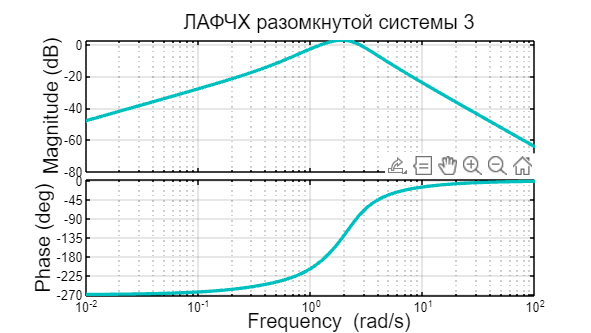

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2);


%{
sys_i = tf(n_coeffs, d_coeffs)

F = tf(n_coeffs, d_coeffs);
%w = linspace(-1000000, 1000000)
nyquist(F);
title("Годограф Найквиста замкнутой системы 1")
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1);
%}

%{
impulse(sys_i, 'm')
legend('y_{i.r.} - симуляция')
title('Весовая функция замкнутой системы 1.')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off

step(sys_i, 'm')
legend('y_{s.r.} - симуляция')
title('Переходная функция замкнутой системы 1.')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off

%}

%{
p_open = solve(dem);
p_close = solve(num+dem);
p_nulls = solve(num);
clf reset;
hold on;
%figure('Position', [1000 0 800 450])
x_open = real(p_open);
x_close = real(p_close);
x_nulls = real(p_nulls);
y_open = imag(p_open);
y_close = imag(p_close);
y_nulls = imag(p_nulls);
%{
x_min = double(min(min(cat(2, x_open, x_close, x_nulls)))-0.2);
x_max = double (max(max(cat(2, x_open, x_close, x_nulls)))+0.2);
y_min = double(min(min(cat(2, y_open, y_close, y_nulls)))-0.2);
y_max = double (max(max(cat(2, y_open, y_close, y_nulls)))+0.2);
%}
k=4
x_min = -k;
x_max = k;
y_min = -k;
y_max = k;

plot([x_min x_max], [0 0], 'k--')
plot([0 0], [y_min y_max], 'k--')

plot(x_open, y_open, "*", Color='red', DisplayName='Полюса: разомкнутая система', LineWidth=1.5)
plot(x_close, y_close, "o", Color='blue', DisplayName='Полюса: замкнутая система', LineWidth=1.5)
plot(x_nulls, y_nulls, "x", Color='green', DisplayName='Нули', LineWidth=1.5)
legend('', '', 'Полюса: разомкнутая система', 'Полюса: замкнутая система', 'Нули')
xlim([x_min x_max])
ylim([y_min y_max])
title('Изображение полюсов и нулей системы 3')
xlabel("Re")
ylabel("Im")
hold off;
%}
